format long
syms f(x) X a b
f(x) = x^3+x-2;      % x is automatically created once f(x) is created.
diffF = diff(f,x)

$$diffF(x) = 3\,x^{2}+1$$

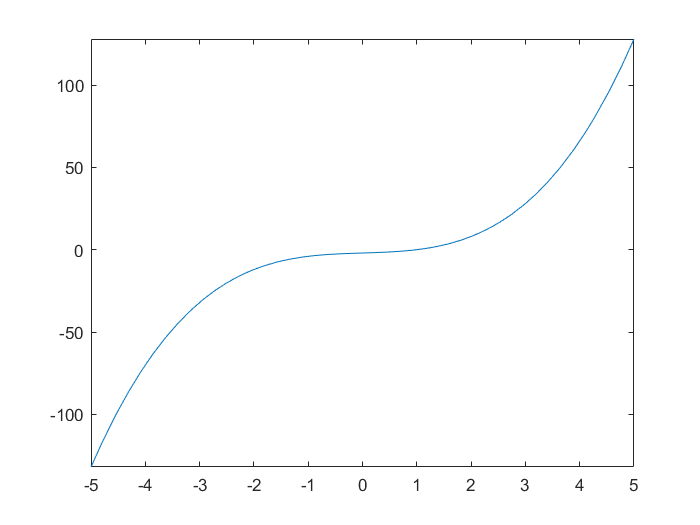

fplot(f)

digitsOld = digits(10);

M = [];
a = 2; b = 1.8;
M(1) = a; M(2) = b;
i = 3;
while (abs(double(f(M(i-1))-f(M(i-2))))> 1e-17)
    X = vpa((M(i-2)*f(M(i-1))-M(i-1)*f(M(i-2)))/(f(M(i-1))-f(M(i-2))))
    M(i)= X;
    b = a;
    a = X;
     if i>=5
        if(abs(M(i)-M(i-1))> abs(M(i-1)-M(i-2)))
            disp('Either diverging or cyclic')
            break
        end
     end
     i = i+1;
end

$$X = 1.324324324$$

$$X = 1.127732593$$

$$X = 1.025911406$$

$$X = 1.002329208$$

$$X = 1.000044735$$

$$X = 1.000000078$$

$$X = 1.0$$

$$X = 1.0$$

$$X = 1.0$$

round(M,6)

ans =    2.000000000000000   1.800000000000000   1.324324000000000   1.127733000000000   1.025911000000000   1.002329000000000   1.000045000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000


eqns = f(x)==0;
Exact_Solution = vpasolve(eqns,x)

$$Exact\_Solution = \left(\begin{array}{c} 1.0\\ -0.5+1.322875656\,\mathrm{i}\\ -0.5-1.322875656\,\mathrm{i} \end{array}\right)$$

Error = abs(Exact_Solution(1) - M(3:i-1)');
Table = vpa([M(3:i-1)' Error])

$$Table = \left(\begin{array}{cc} 1.324324324 & 0.3243243243\\ 1.127732593 & 0.127732593\\ 1.025911406 & 0.02591140609\\ 1.002329208 & 0.002329207943\\ 1.000044735 & 0.00004473513624\\ 1.000000078 & 0.00000007807080604\\ 1.0 & 2.61923816e-12\\ 1.0 & 1.353054225e-26\\ 1.0 & 1.353054225e-26 \end{array}\right)$$

% Order of Convergence
format long
n = length(Error)-1

n =      8


r = log(Error(1:n));
s = log(Error(2:n+1));
sumr=0.00; sums = 0.00; sumr2 = 0.00; sumrs=0.00;
for i = 1:n
    sumr = sumr+r(i);
    sumr2 = sumr2 + r(i)^2;
    sums = sums + s(i);
    sumrs = sumrs + r(i)*s(i);
end
Order_of_Convergence = vpa((sumr*sums-n*sumrs)/(sumr^2-n*sumr2))

$$Order\_of\_Convergence = 0.7338451149$$